#   **Lab Endsem (190020021)**

## **Designing FIR and IIR filter to denoise given audio signal**

**FIR Filter:**

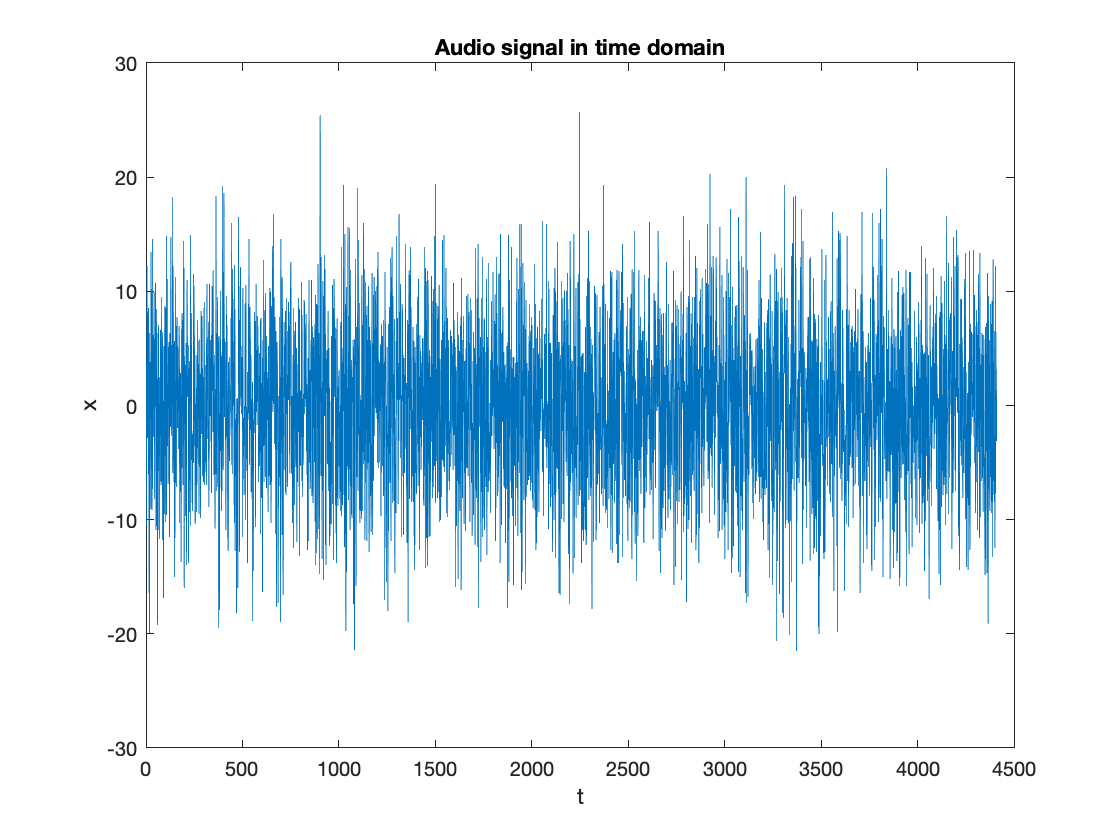

%Importing audio data from .mat file
load("DSPLab_EndSem2021_DataFileFor_190020021.mat");
%Playing the audio signal
%sound(x,44100);
%Plotting in time domain
plot(x(1:4410))
xlabel("t")
ylabel("x")
title("Audio signal in time domain")

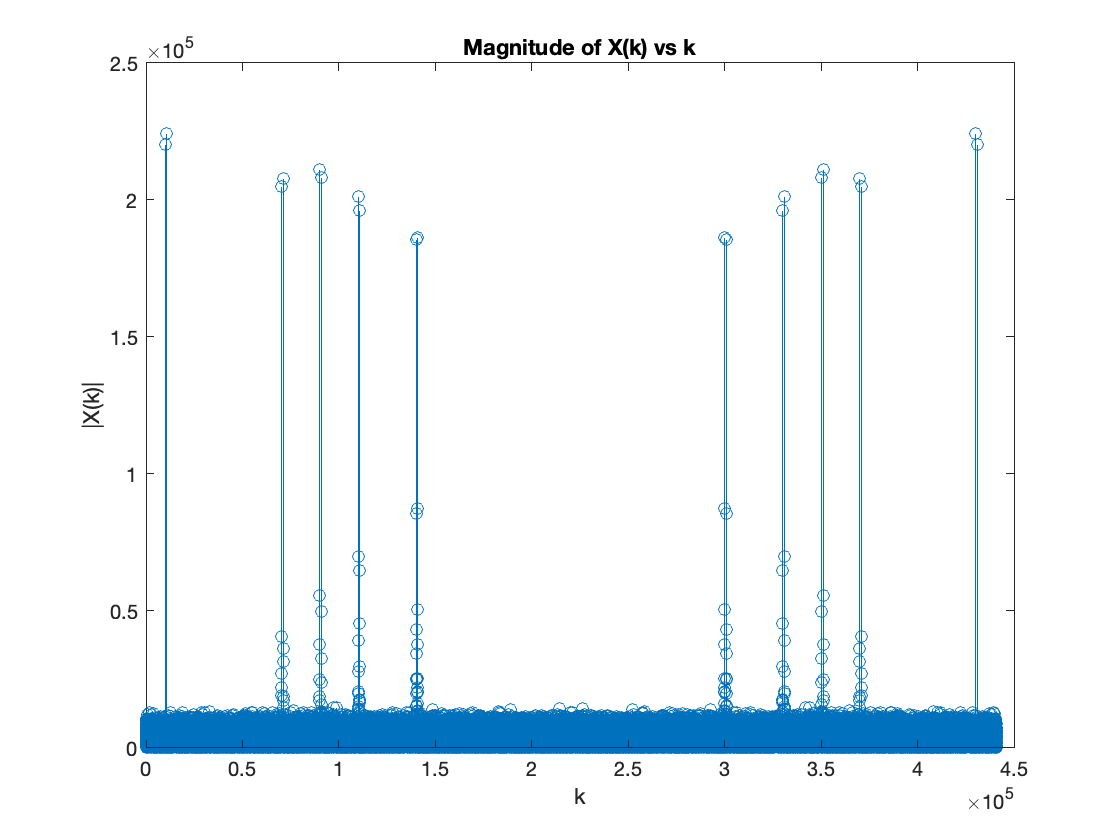

%Taking FFT of the audio signal to visualize frequency components
x_fft = fft(x);
%Plotting fft
stem(abs(x_fft))
xlabel("k")
ylabel("|X(k)|")
title("Magnitude of X(k) vs k")

%Designing a high pass FIR filter
Fs = 44100;  % Sampling Frequency

Fstop = 7100;     % Stopband Frequency
Fpass = 8000;     % Passband Frequency
Dstop = 0.01;     % Stopband Attenuation
Dpass = 0.01;     % Passband Ripple
flag  = 'scale';  % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs/2), [0 1], [Dpass Dstop]);
%Filter coefficients
b  = double(fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag));

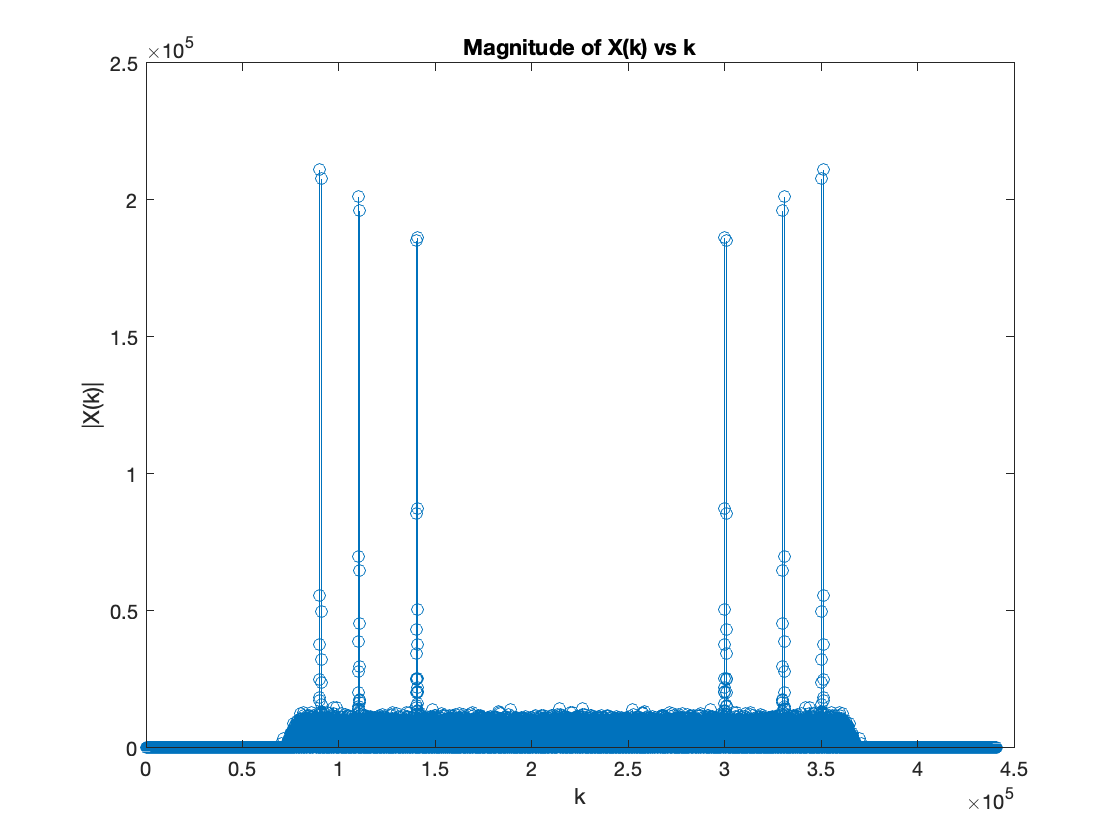

%filtering the audio signal using designed filter
x_filtered = filter(b,1,x);
%Take fft
x_filt_fft = fft(x_filtered);
%Plotting absolute value of the fft of the filtered signal
stem(abs(x_filt_fft))
xlabel("k")
ylabel("|X(k)|")
title("Magnitude of X(k) vs k")

%sound(x_filtered,44100)

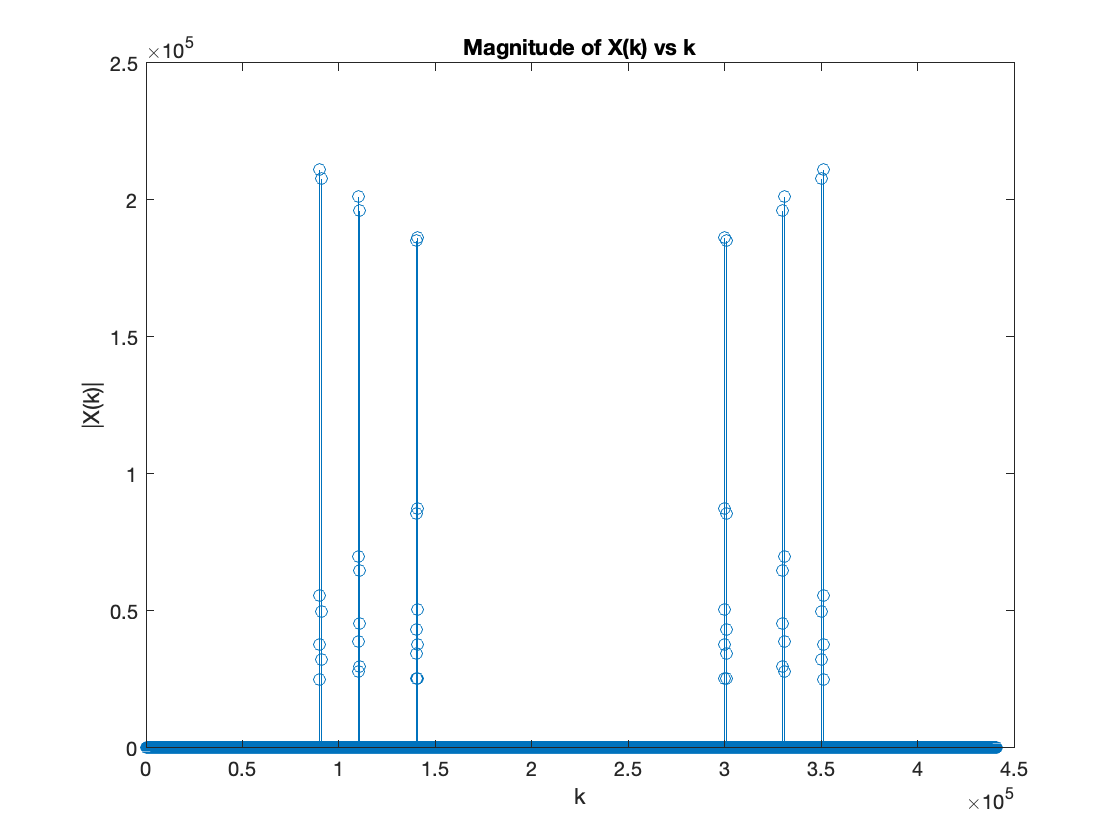

%Removing noise from the audio signal
for i=1:length(x_filt_fft)
    if(abs(x_filt_fft(i))<0.1*2.5*(10^5))
        x_filt_fft(i) = 0;
    end
end
%Plot absolute value of denoised function
stem(abs(x_filt_fft))
xlabel("k")
ylabel("|X(k)|")
title("Magnitude of X(k) vs k")

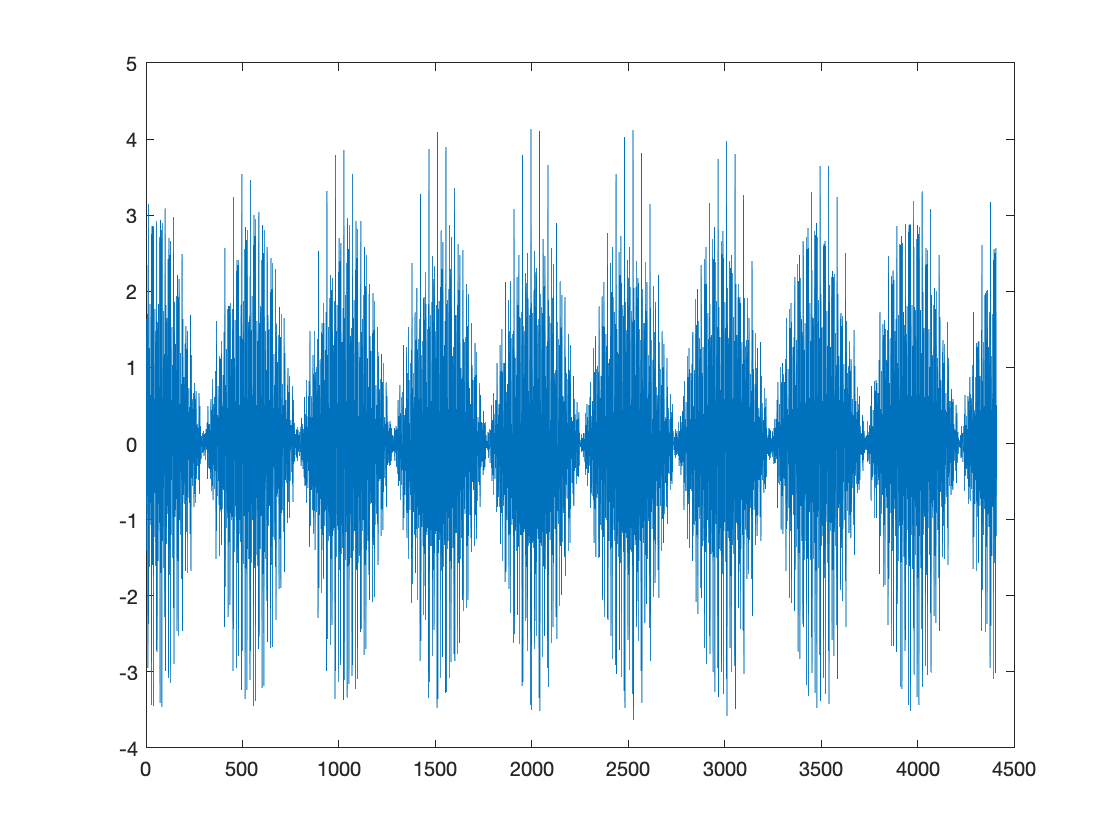

%Take inverse fft of the denoised signal
x_filt_ifft = ifft(x_filt_fft);
plot(x_filt_ifft(1:4410))

%sound(x_filt_ifft,44100)

**IIR Filter:**

%Designing high pass IIR filter
Fstop = 7700;     % Stopband Frequency
Fpass = 8000;     % Passband Frequency
Astop = 20;       % Stopband Attenuation (dB)
Apass = 10.4576;  % Passband Ripple (dB)
Fs    = 44100;    % Sampling Frequency
h = fdesign.highpass('fst,fp,ast,ap', Fstop, Fpass, Astop, Apass, Fs);

Hd = design(h, 'butter', ...
'MatchExactly', 'stopband', ...
'SystemObject', true);

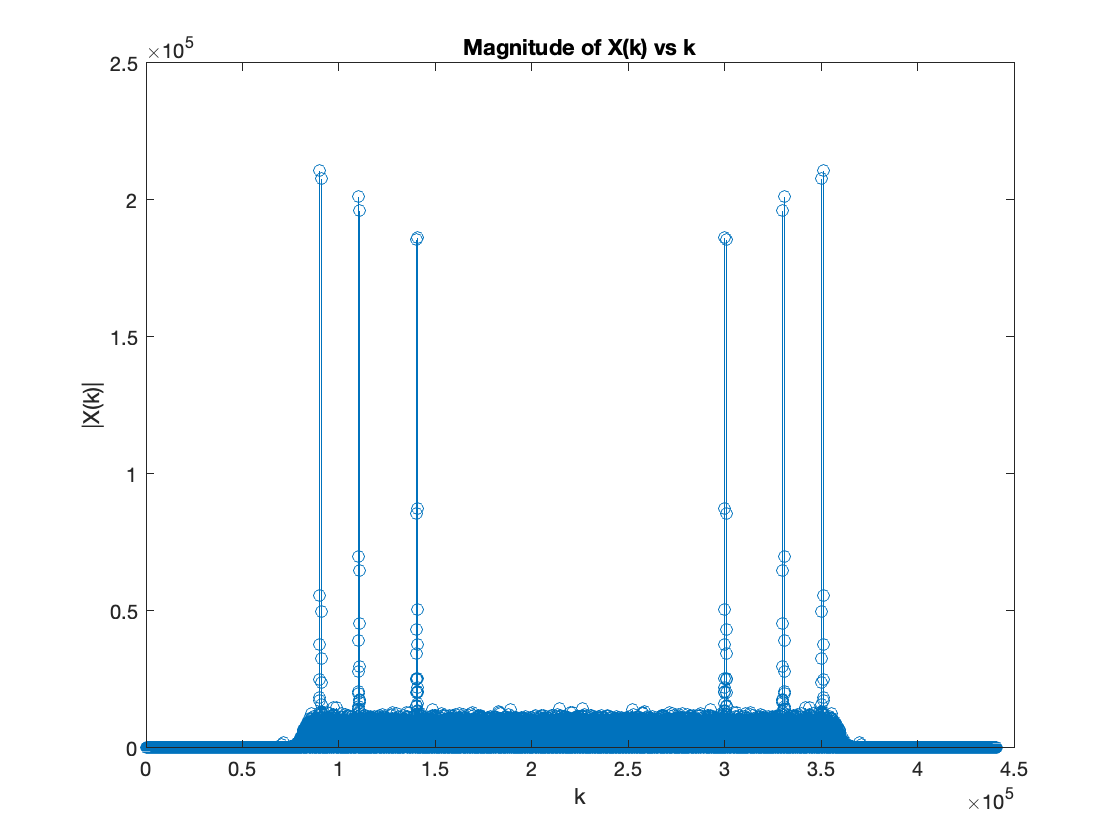

y_filt = step(Hd,x);

y_filt_fft = fft(y_filt);

stem(abs(y_filt_fft))
xlabel("k")
ylabel("|X(k)|")
title("Magnitude of X(k) vs k")

%Removing noise from the audio signal
for i=1:length(x_filt_fft)
    if(abs(x_filt_fft(i))<0.1*2.5*(10^5))
        x_filt_fft(i) = 0;
    end
end
%Plot absolute value of denoised function
stem(abs(x_filt_fft))
xlabel("k")
ylabel("|X(k)|")
title("Magnitude of X(k) vs k")

%Take inverse fft of the denoised signal
x_filt_ifft = ifft(x_filt_fft);
plot(x_filt_ifft(1:4410))

%sound(x_filt_ifft,44100)

#### **Quantizing coefficients to 4 bits:**

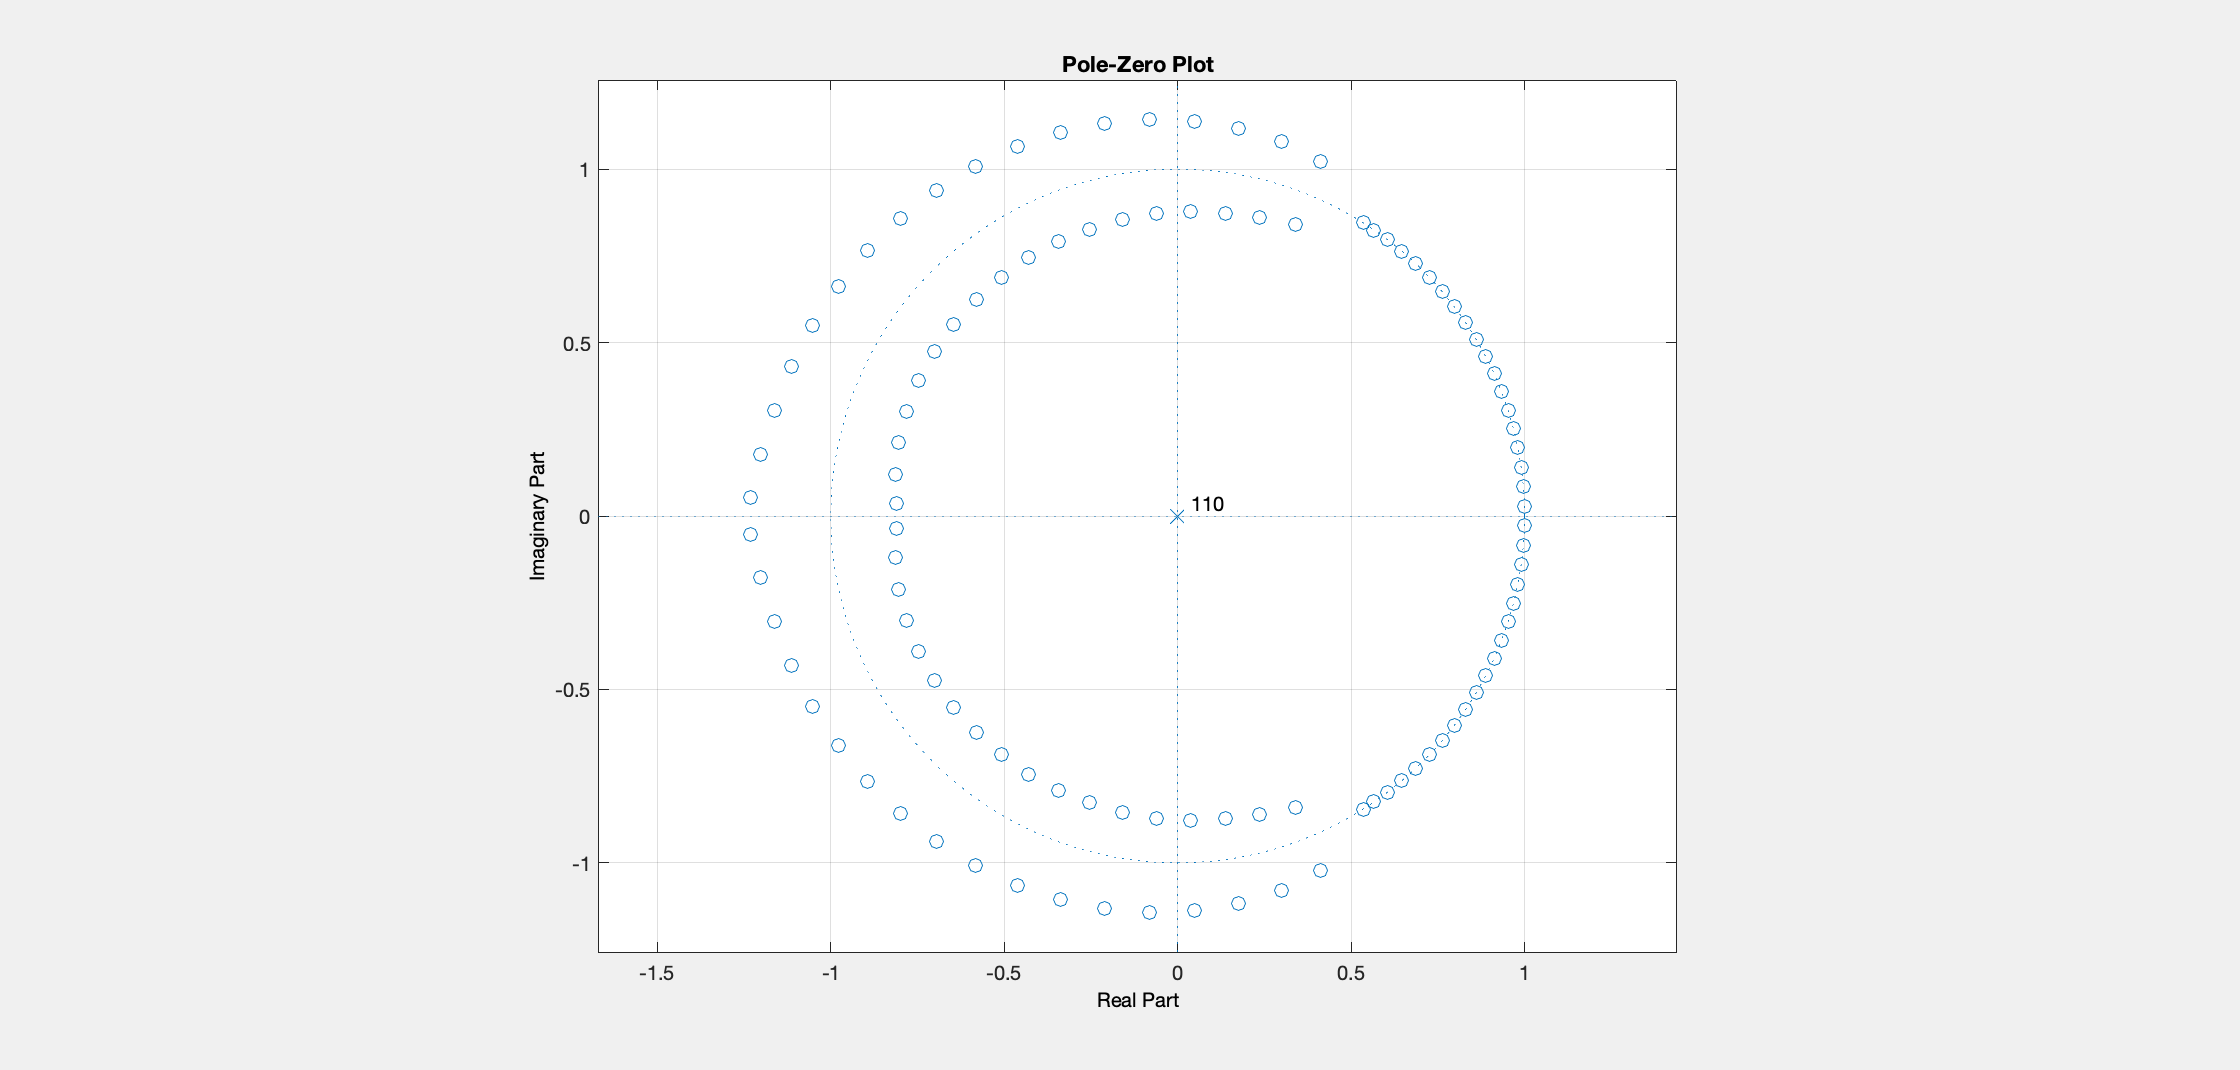

%FIR coefficients
N = 4;
range = 2^(N-1);
b_4bit = round(b * range ) / range;

fvtool(b,'polezero')

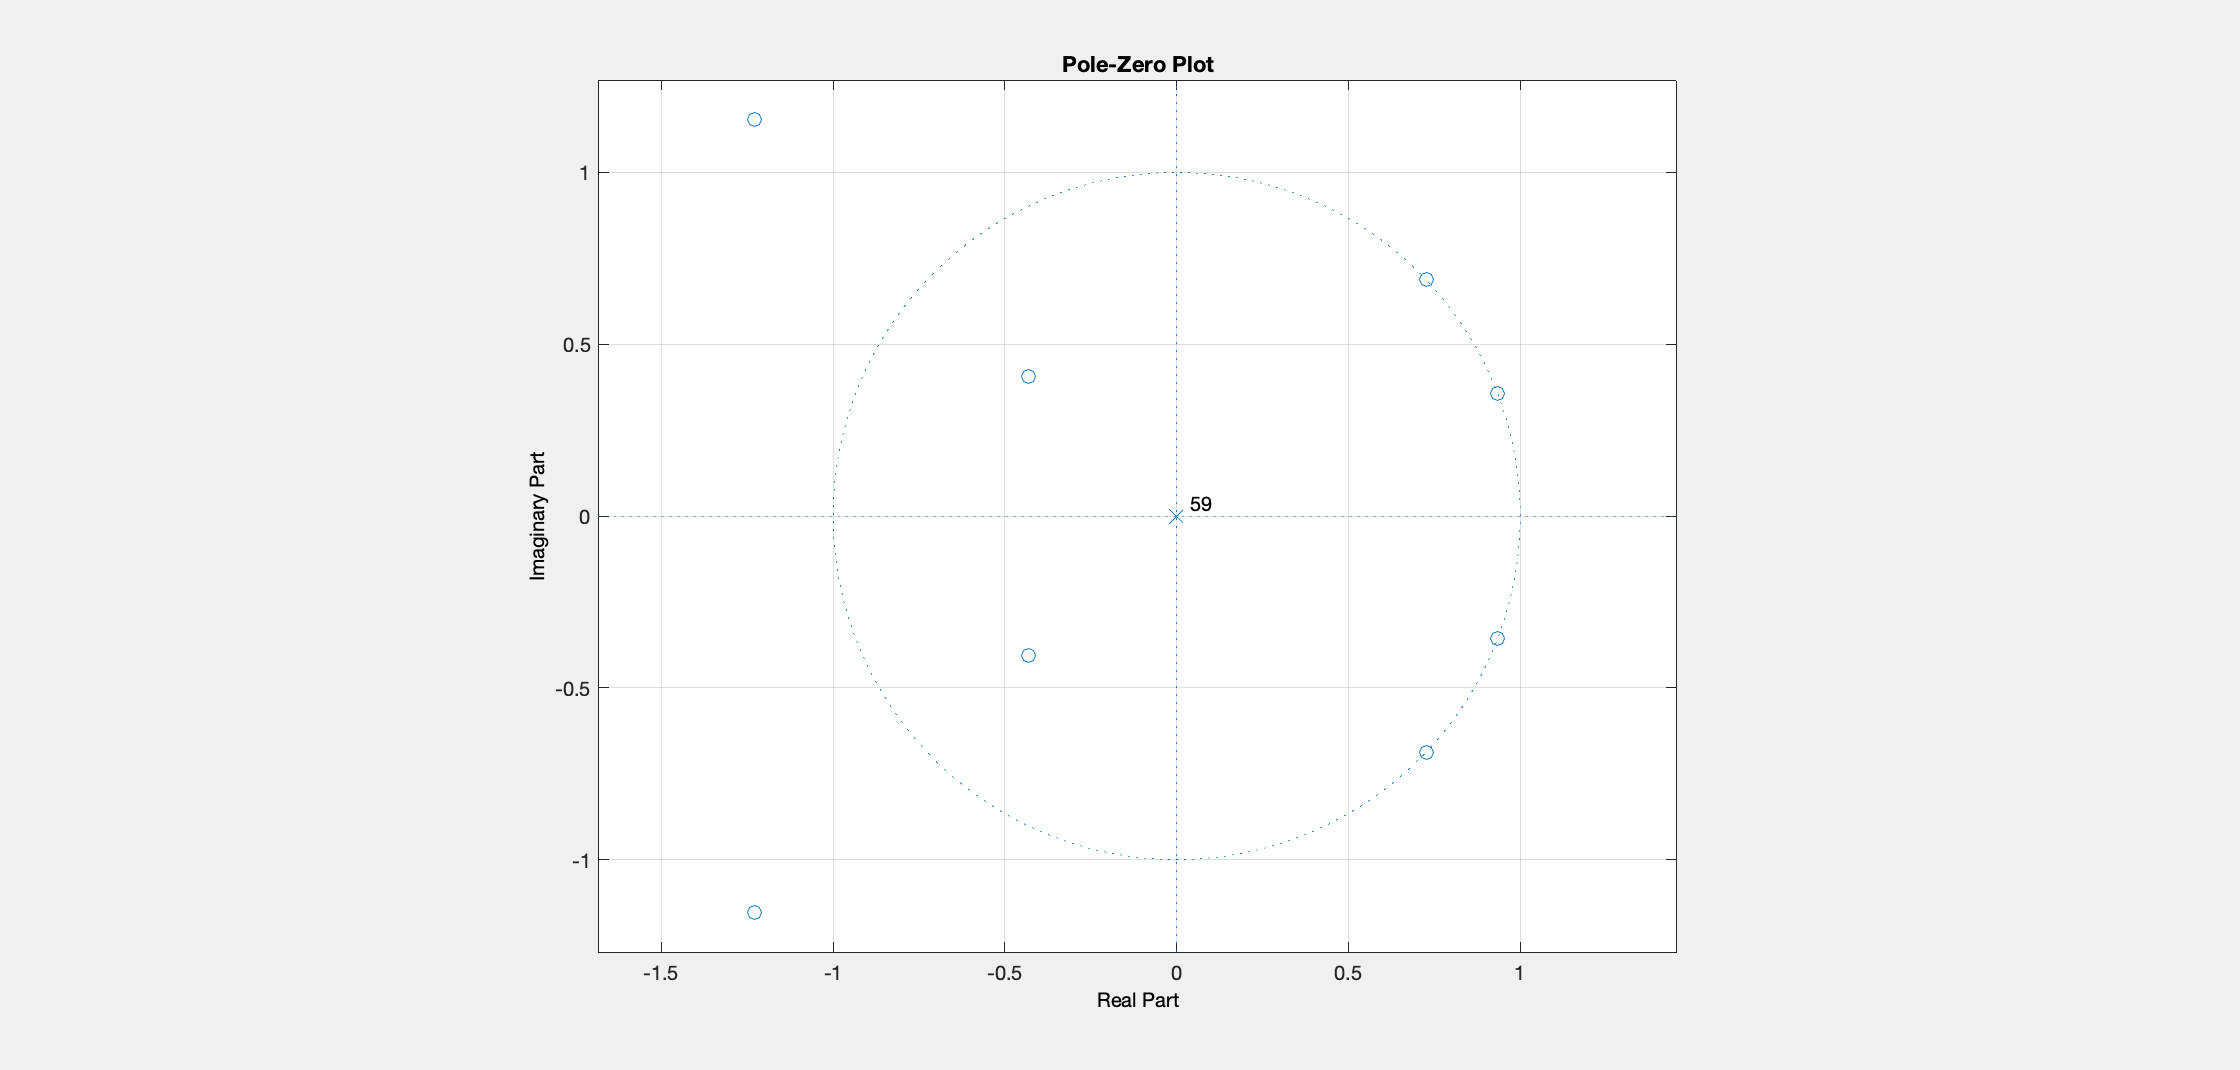


fvtool(b_4bit,'polezero')

Hd

Hd =   dsp.BiquadFilter with properties:

                   Structure: 'Direct form II'
             SOSMatrixSource: 'Property'
                   SOSMatrix: [13×6 double]
                 ScaleValues: [14×1 double]
           InitialConditions: 0
    OptimizeUnityScaleValues: true

  Show all properties


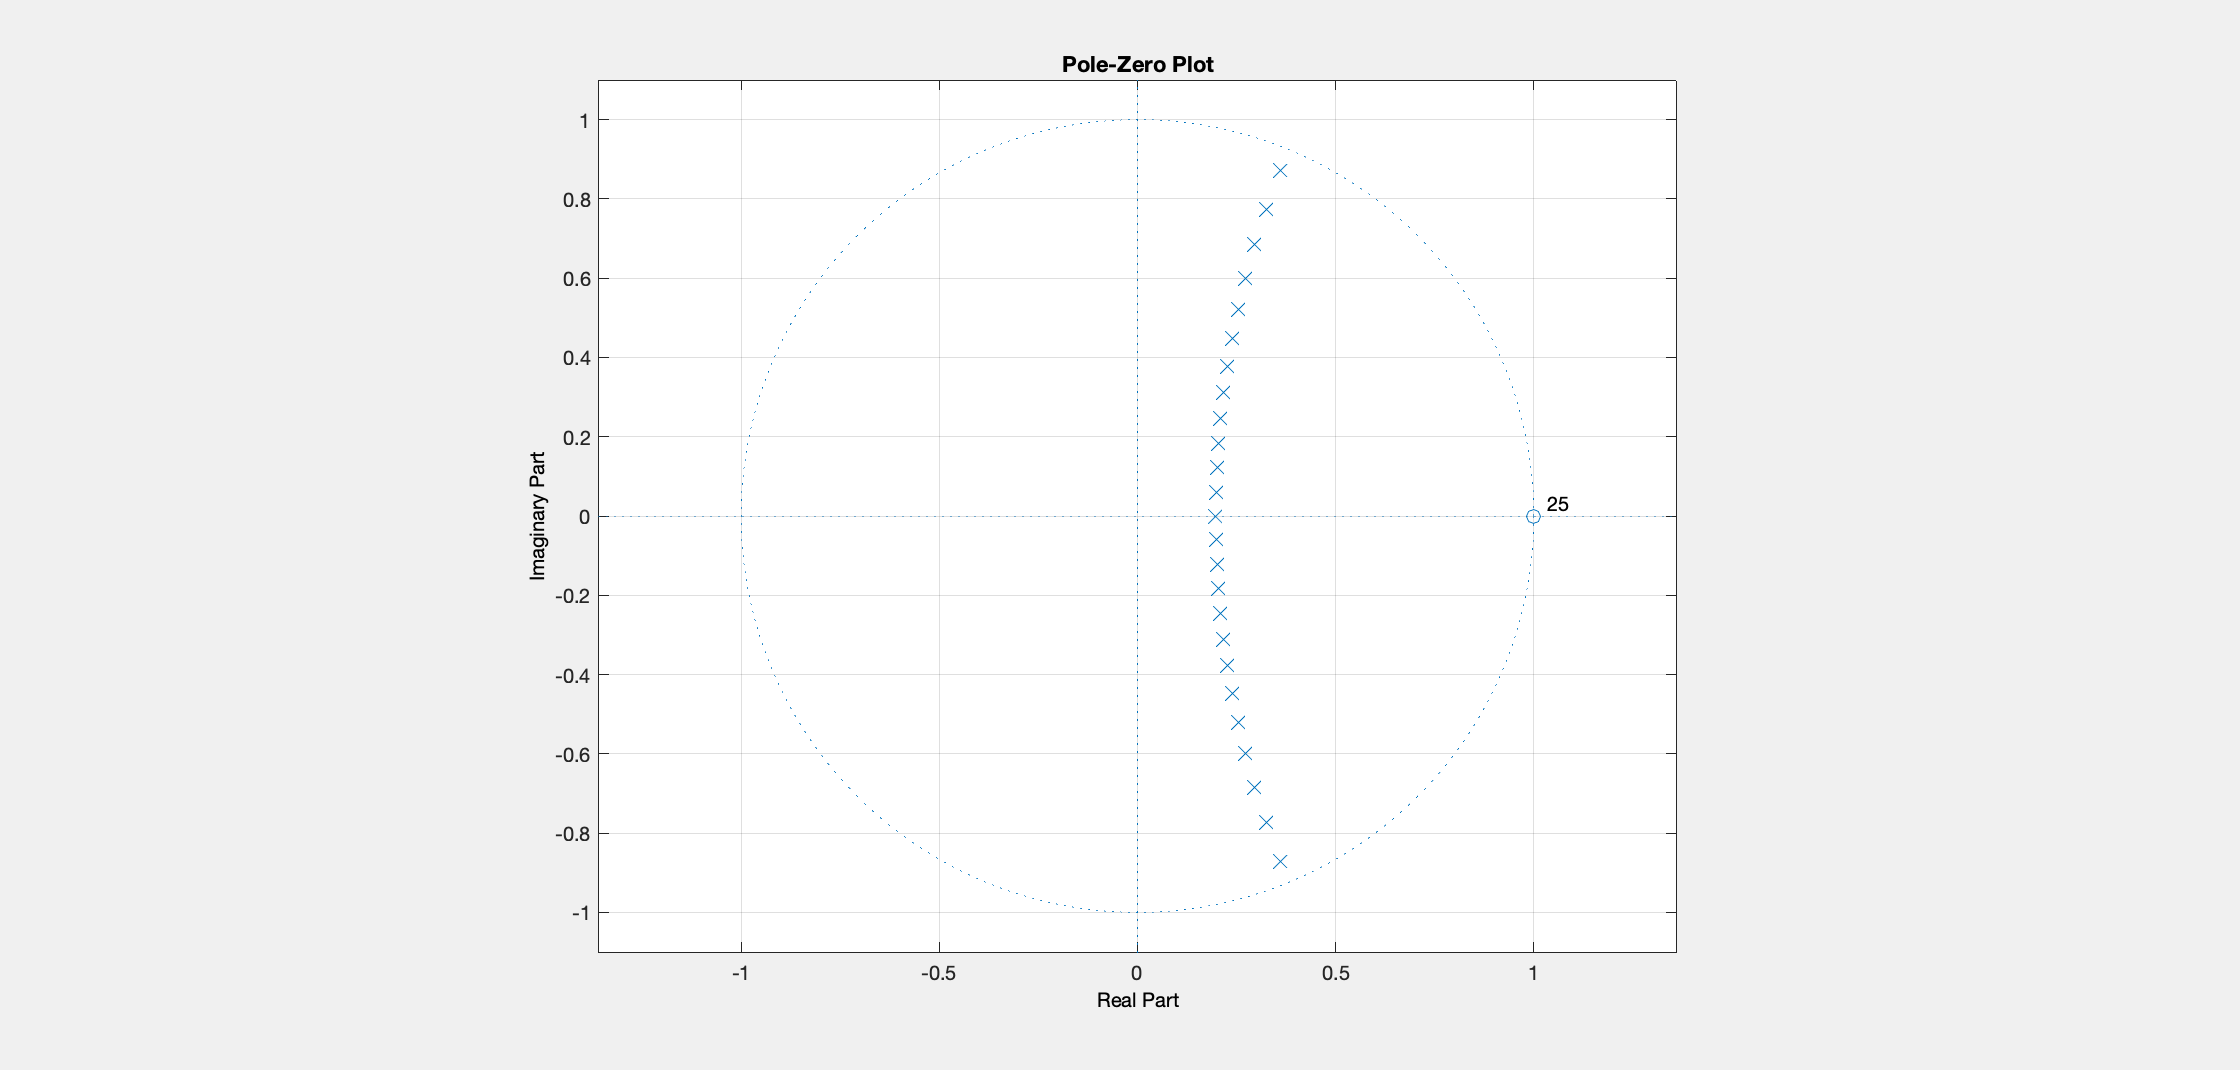

fvtool(Hd.SOSMatrix,'polezero')

coeffs = Hd.SOSMatrix;
max(max(coeffs))

ans = 1

min(min(coeffs))

ans = -2

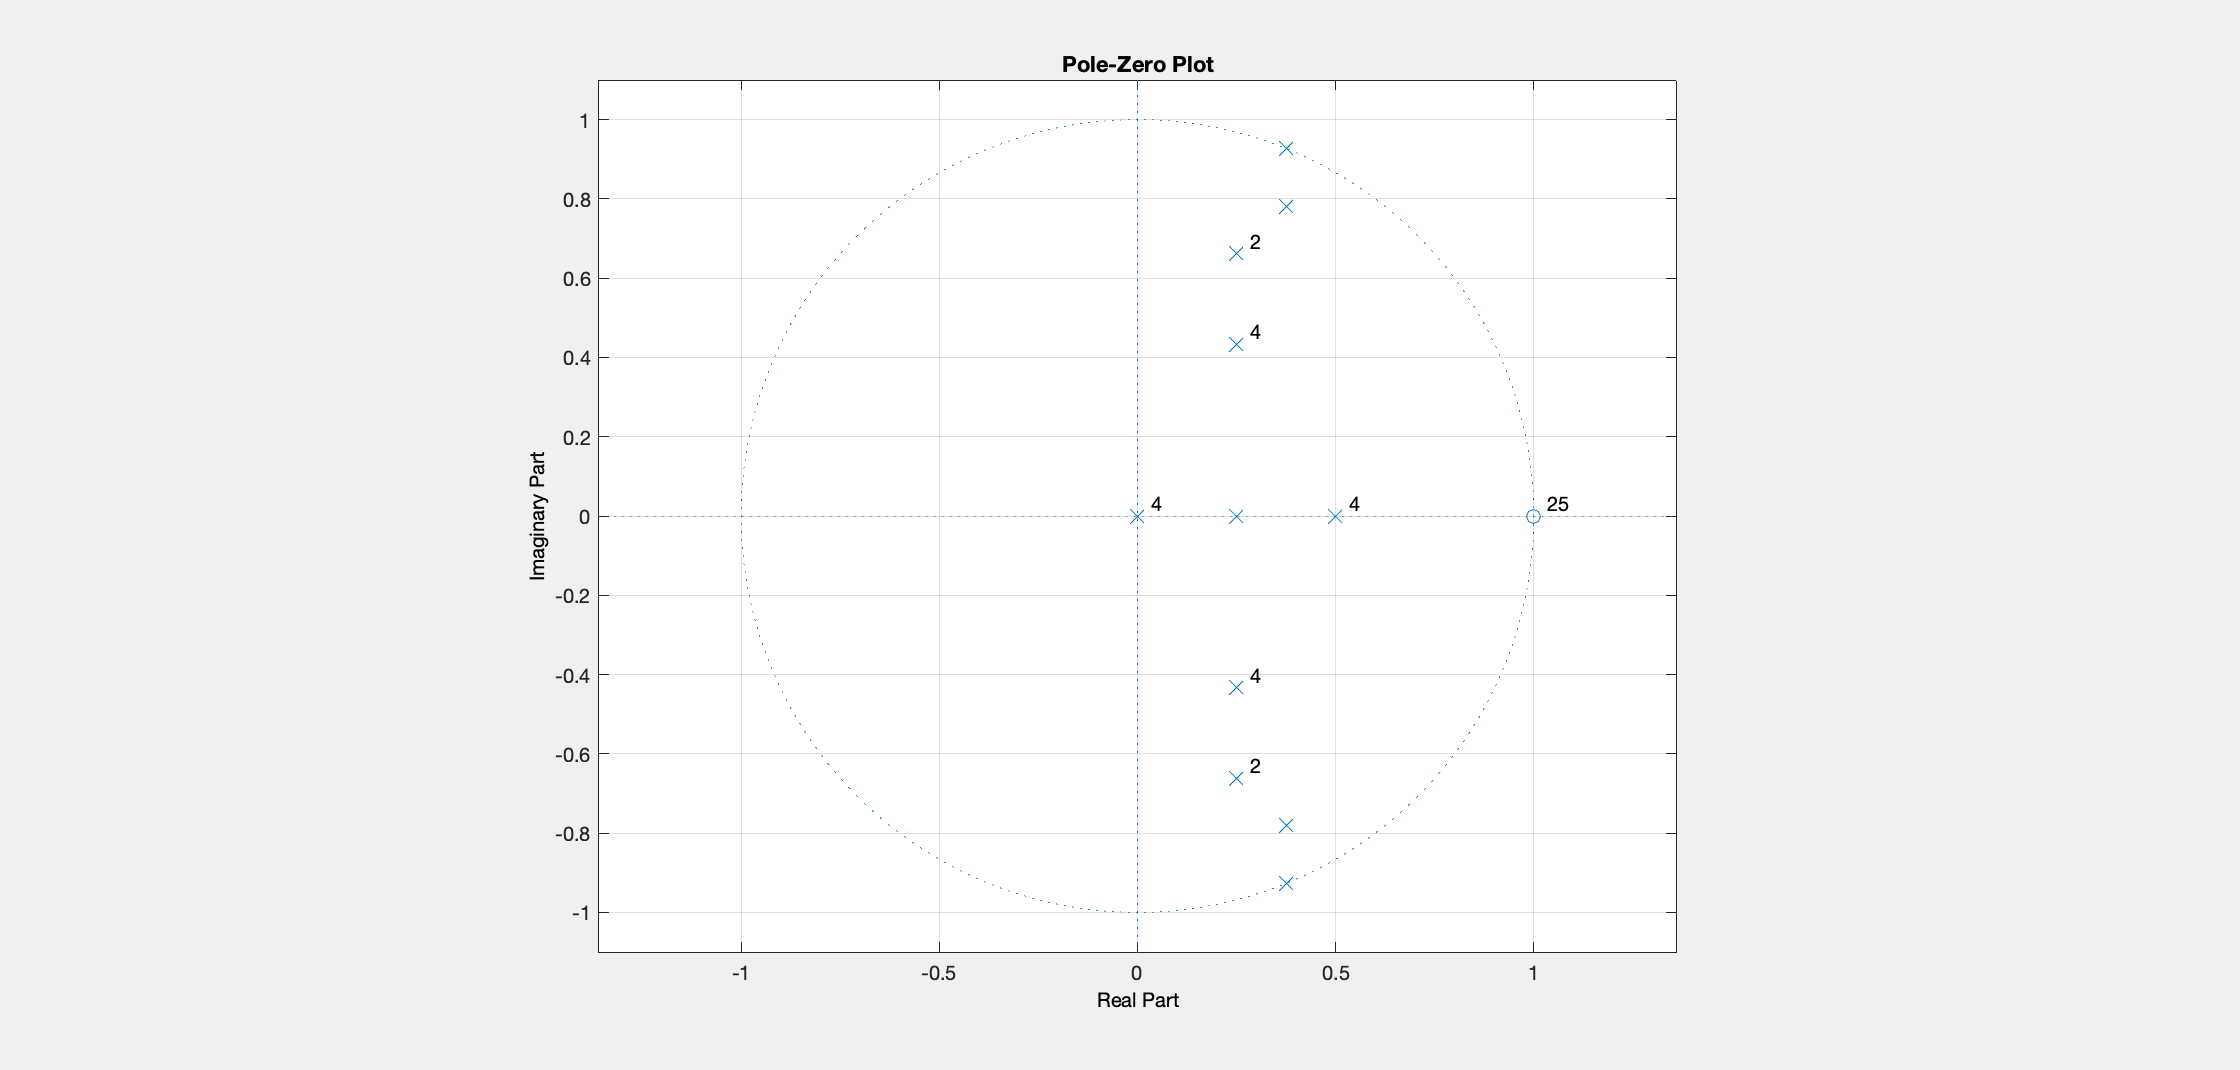

%IIR coefficients
N = 4;
range = 2^(N-1);
coeffs_4bit = round(coeffs * 2^2 ) / 2^2;
fvtool(coeffs_4bit,'polezero')